% IGNORA DA QUI --- stavo controllando i conti di questo paper indiano - che sono sbagliati

% Dati presi da https://www.researchgate.net/publication/330667413_Tuning_PID_Controllers_for_DC_Motor_by_Using_Microcomputer
% dati indiani
% Ra = 1.9;
% La = 65e-6;
% Kb = 0.0134;
% Bd  = 0.001; %B damping factor
% J  = 57e-7;
% Kt = 0.0134;

% numeratore = Kt * 1/ (La * J)
% diff1 = numeratore - 3.616e8
% termines = (Ra * J + La * Bd) / (La * J)
% terminenotoden = (Ra * Bd + Kb * Kt) / (La * J)
% diff2 = terminenotoden - 5.611e7

% IGNORA FINO A QUI


% https://www.maxongroup.com/maxon/view/product/motor/dcmotor/re/re25/339150

% dati maxon
Ra = 0.517;%[ohm]
La = 0.0573e-3; %[H] 

% Kb: La costante di back EMF è calcolata convertendo la costante di velocità da rpm/V a V/rad/s. 
% La conversione utilizza il fattore di conversione 2π/60 per passare da giri al minuto a radianti al secondo.
% 828 rpm = 86.7 rad/s
% 828 [rpm / V] = 86.7 [(rad/s)/V] => [V/(rad/s)] 1/86.7 = 0.115 V/(rad/s)
Kboriginale = 828 % preso dalle specs, [rpm/V]

Kboriginale = 828

Kbintermedio = 828 * (2 * pi / 60); % [(rad/s)/V]
Kb = 1 / Kbi; % [V/(rad/s)]

Bd = 0.001; %B damping factor stimato
J  = 14.5e-7; % [kg⋅m^2] convertito dalle specs
Kt = 11.5e-3; % [N·m/A] convertito dalle specs


A = [ -Ra/La 0  -Kb/La ; 
      0      0       1 ;
      Kt/J   0   -Bd/J ];

B = [1/La ; 0 ; 0 ];

C = [ 0 1 0 ];

D = [];    % Matrice nulla


% Creazione del sistema nello spazio di stato
sys = ss(A, B, C, D);
eigenvalues = eig(A)

eigenvalues = 1.0e+03 *

         0
   -8.8265
   -0.8858


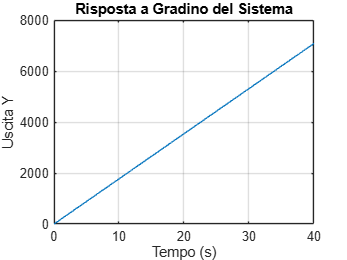


% Simulazione della risposta a gradino
T = 0:0.01:40;
U_step = 10 * ones(size(T));
[Y_step, T_step] = lsim(sys, U_step, T);
figure;
plot(T_step, Y_step);
title('Risposta a Gradino del Sistema');
xlabel('Tempo (s)');
ylabel('Uscita Y');
grid on;

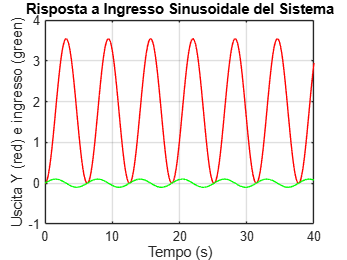


% Simulazione della risposta a un ingresso sinusoidale
U_sine = 0.1 * sin(T);
%U_sine = sin(T);
[Y_sine, T_sine] = lsim(sys, U_sine, T);
figure;
%plot(T_sine, Y_sine);
plot(T_sine, Y_sine,"red",T_sine, U_sine,"green")
title('Risposta a Ingresso Sinusoidale del Sistema');
xlabel('Tempo (s)');
ylabel('Uscita Y (red) e ingresso (green)');
grid on;

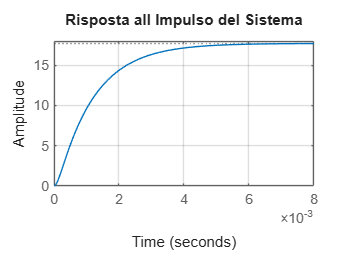


% Risposta all'impulso
figure;
impulse(sys);
title('Risposta all Impulso del Sistema');
grid on;

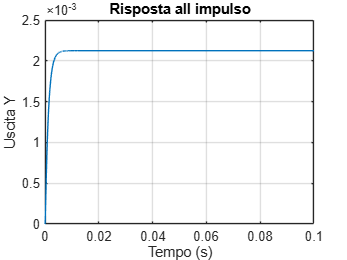


%T = 0:0.01:40;
T = 0:0.00001:0.1;
U_impulse = zeros(size(T));
U_impulse(1) = 12;
[Y_impulse, T_impulse] = lsim(sys, U_impulse, T);
figure;
plot(T_impulse, Y_impulse);
title('Risposta all impulso');
xlabel('Tempo (s)');
ylabel('Uscita Y');
grid on;


% Analisi con Linear System Analyzer
%linearSystemAnalyzer('step', sys);
